# Fitting a 4D SSM for an internally resonant (1:3) prismatic beam

See [1] for the details of this model, and [2] the description of this example.

[1] Li, M., Jain, S., & Haller, G. (2021). Nonlinear analysis of forced mechanical systems with internal resonance using spectral submanifolds-Part I: Periodic response and forced response curve. *Nonlinear Dynamics* 110, 1005-1043. [DOI: 10.1007/s11071-022-07714-x](https://doi.org/10.1007/s11071-022-07714-x)

[2] Cenedese, M., Marconi, J., Haller, G., & Jain, S. (2023). Data-assisted non-intrusive model reduction for forced nonlinear finite elements models. Preprint: [arXiv: 2311.17865](https://arxiv.org/abs/2311.17865) 

clearvars
close all
format shortg
clc

% Setup colors
colors = colororder; colSSMT = 5; colSSML = 7; colFOM = 1;

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}   & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}   \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

epsilon = 1e-4;
c  = 100;
f = 5/epsilon;
n = 10;               % number of modes
Fext = zeros(n,1);    % excitation at modal coordinate
Fext(1) = f;
[M,C,K,fnl,fext] = buildModel(c,Fext,epsilon,n);

Getting nonlinearity coefficients
Loaded coefficients from storage


outdof = [1];

Preliminaries

if ~isfile('init.mat')
    [F, lambda] = functionFromTensors(M, C, K, fnl); d_r1 = -real(lambda(1))/abs(lambda(1))*100
    m = 10;
    [W,A,V,lambda] = linearpart(M,C,K,m);
    save('init.mat',"W","A","V","F","lambda")
else
    load('init.mat')
end

## Define master modes and linear part of the dynamics 

Due to the 1:3 internal resonance, we take the first two complex conjugate pairs of modes as the spectral subspace to SSM. So we have resonant_modes = [1 2 3 4].

masterModes = [1 3 2 4]; % Modal displacements and modal velocities
Ve = V(:,masterModes); % Mode shape
We = W(masterModes,:); % Projection to mode shape
Ae = full(We*A*Ve) % Reduced, linearized dynamics

Ae =             0            0            1            0
            0            0            0            1
      -14.864            0        -0.02            0
            0      -156.07            0        -0.02


SSMDim = length(masterModes);

% Load and displacement vector: midpoint displacement
displacementVector = zeros(1,n); displacementVector(outdof) = 1;
loadVector = fext;  %  could also be set as modal ones

## Compare linear and nonlinear response via modal displacement

This is performed in order to obtain initial conditions of the the decaying trajectories.

Model = struct('M', M ,'K', K, 'F',F); 

Displacement along the first mode

Solving undamped eigenvalue problem
Mode shape
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0

Eigenfrequency
       3.8553



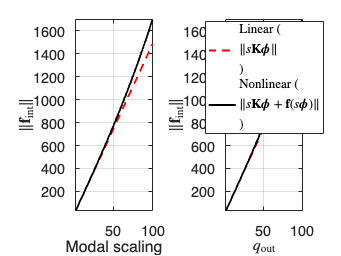

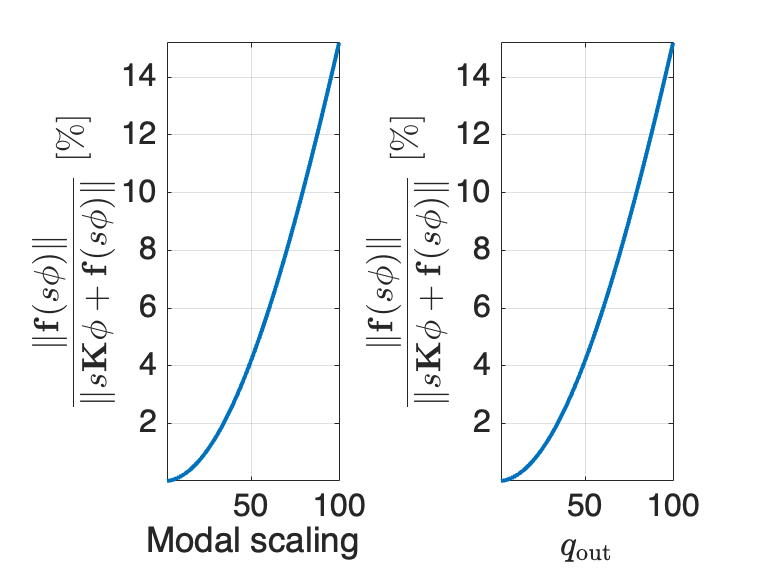

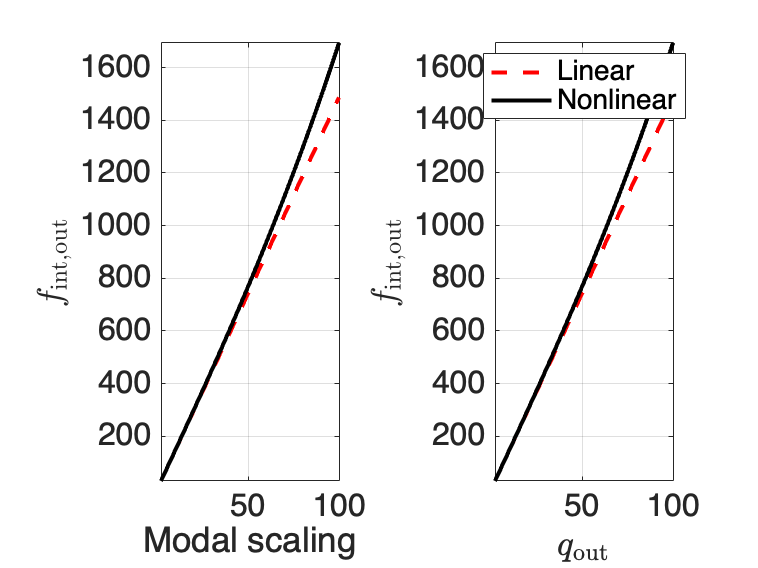

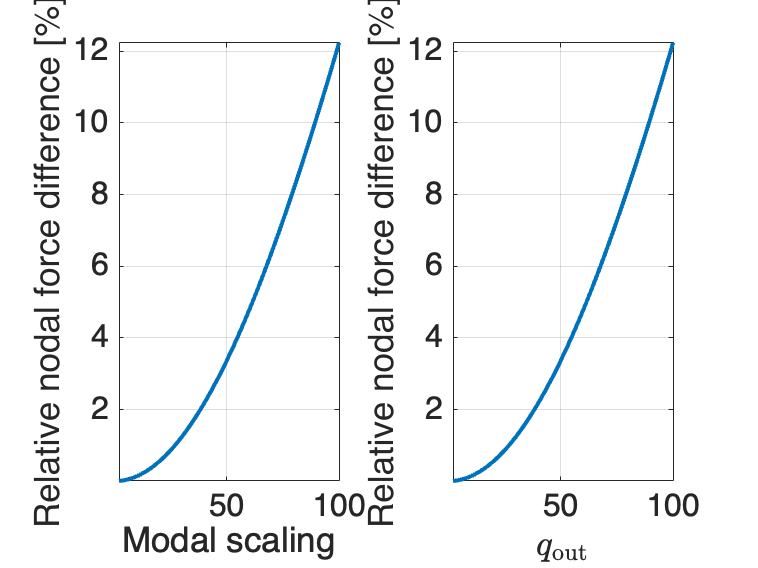

Displacement at output DOF: 100


iMode = 1; scalingfactor1 = 1e2; nsteps = 50; outdof1 = 1;
[phi1, relativeDiffForceNorm] = modal_analysis(Model,scalingfactor1,nsteps,outdof1,false,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC1 = [nsteps, nsteps-1];
IC1 = [phi1*(scalingfactor1*indIC1/nsteps);zeros(n,length(indIC1))];

Displacement along the second mode

Solving undamped eigenvalue problem
Mode shape
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0

Eigenfrequency
       12.493



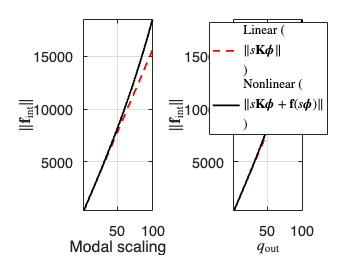

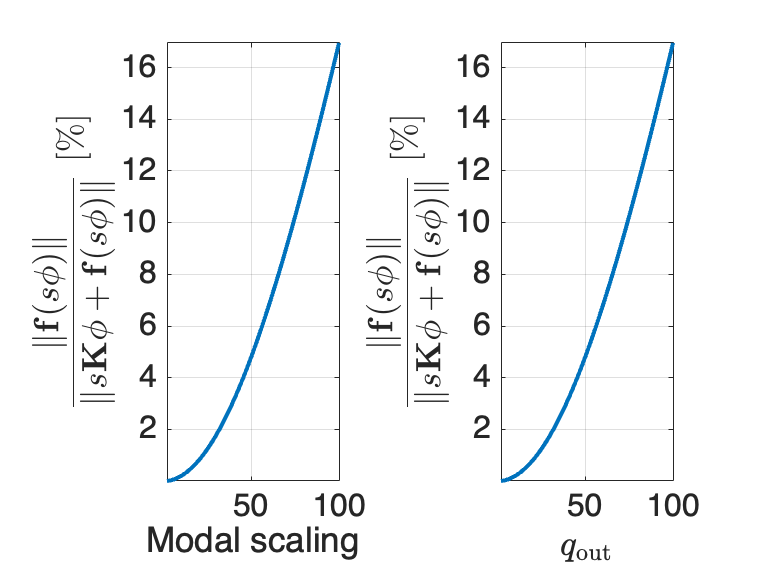

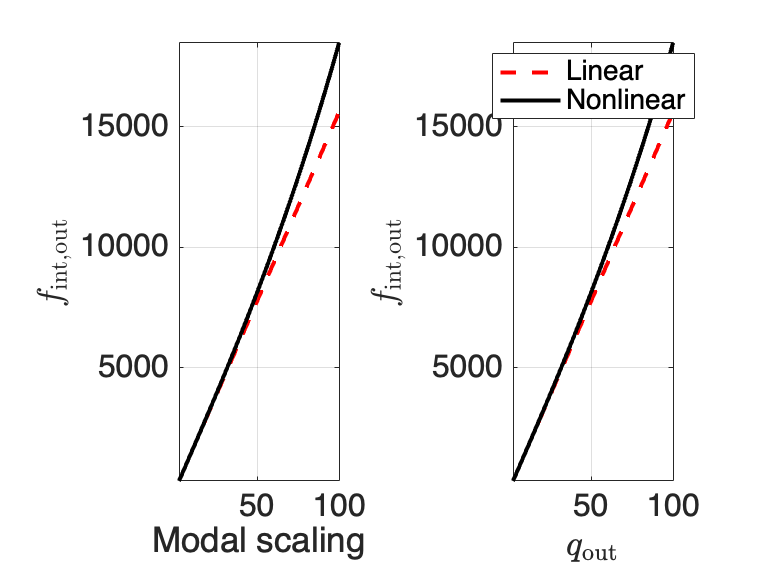

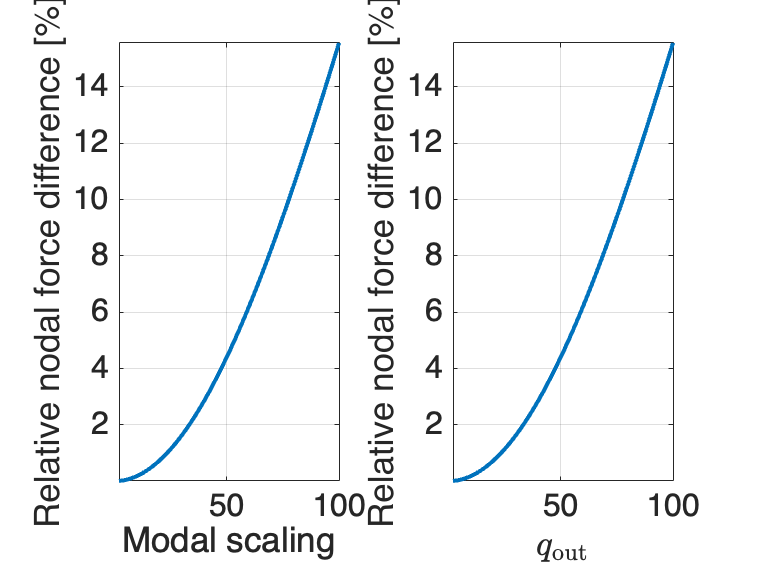

Displacement at output DOF: 100


iMode = 2; scalingfactor2 = 1e2; nsteps = 50; outdof2 = 2;
[phi2, relativeDiffForceNorm2] = modal_analysis(Model,scalingfactor2,nsteps,outdof2,false,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC2 = [nsteps, nsteps-1];
IC2 = [phi2*(scalingfactor2*indIC2/nsteps);zeros(n,length(indIC2))];

Pick combination of initial conditions along the both the modes for training and testing

a = rand; b = rand; 
ICs = [IC1, IC2, a*IC1 + b*IC2];
indTrain = [1 3 5];
indTest = [2 4 6];

Define the linear regime at 1 % relative force

linearDisplacementReference = scalingfactor1*(sum(relativeDiffForceNorm<1)+1)/nsteps;
nonlinearDisplacementReference = scalingfactor1*max(indIC1)/nsteps;
desiredAmplitudeDecay = nonlinearDisplacementReference/linearDisplacementReference;

## **Generate decaying trajectories via time integration**

We use a pre-computed data set.

newSimulation = false;
observable = @(x) x; % Observe the full phase space
slowTimeScale = 2*pi/abs(lambda(1));
fastTimeScale = 2*pi/abs(lambda(round(SSMDim/2)));
if newSimulation
    % Set integration time to get approximately the desired ampltiude decay
    % to get to the linear regime (guess based on linearized damping)
    numberPeriodsSlow = floor(log(desiredAmplitudeDecay)/...
        (2*pi*(-real(lambda(1))/abs(lambda(1)))))
    endTime = numberPeriodsSlow*slowTimeScale;
    % Set the sampling time to capture approximately 100 points per period 
    % on the faster time scale
    numberPeriodsFast = floor(endTime/fastTimeScale);
    numberPointsPerPeriod = 50;
    nSamp = numberPeriodsFast*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    % Integrate
    xData = integrateTrajectories(F, endTime, ICs, nSamp, observable);
    DataInfo = struct('n', n, 'loadvector', loadVector);
    save('dataPrismaticDecayModal.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp')
else
    load dataPrismaticDecayModal.mat
    if n ~= DataInfo.n
       error('The loaded data comes from a model with a different number of elements.') 
    end
end

## Visualize data

yData = coordinatesEmbedding(xData, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


Data filtering: We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the beam tip displacement. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

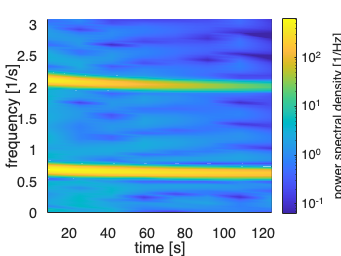

indPlot1 = indTrain(2);
indPlot2 = indTest(2);

showSpectrogram(yData(indPlot1,:), outdof);
ylim([0,abs(lambda(1))/2/pi*5])

We plot the tip displacement over time for closer inspection. 

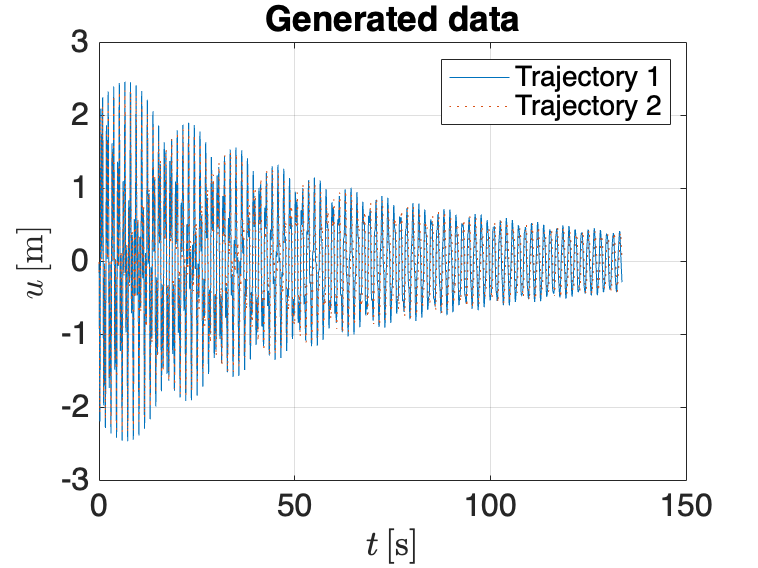

customFigure();
plot(xData{indPlot1,1}, xData{indPlot1,2}(outdof,:), xData{indPlot2,1}, xData{indPlot2,2}(outdof,:), ':');
xlabel('$t \, [$s$]$','Interpreter','latex'); ylabel('$u \, [$m$]$','Interpreter','latex'); 
legend({'Trajectory 1', 'Trajectory 2'})
title('Generated data')

## Truncate transient data from trajectories

Next, we use the information from the spectrogram and plot to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. In this case, faster modes die out very quickly, so we can use almost all of the data. We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval |sliceInt|.

sliceInt = [20*slowTimeScale, endTime];
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates $\eta =W_e y$ of the eigenspace represenation $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. The coefficients $H$are obtained via regression.

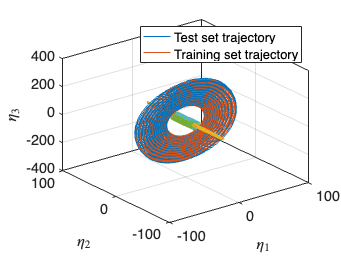

SSMOrder = 3;

% Get projection or modal coordinates 
SSMDim = size(Ve,2);
etaDataTrunc = yDataTrunc;
nTraj = size(yDataTrunc,1);
for iTraj = 1:nTraj
    etaDataTrunc{iTraj,2} = We*yDataTrunc{iTraj,2};    
end

% Plot reduced coordinates
plotReducedCoordinates(etaDataTrunc);
legend({'Test set trajectory', 'Training set trajectory'})
if SSMDim>2
   view(3) 
end


% Compute nonlinear part of the parametrization
IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim,SSMOrder,...
         'reducedCoordinates',etaDataTrunc(indTrain,:),'Ve',Ve,'outdof',outdof); 
IMInfo.chart.map = @(x) We*x;                          

% Parametrization error on test trajectory
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,...
    etaDataTrunc), yDataTrunc);
staticNMTE = mean(normedTrajDist(indTest))*100; % in percentage

disp(['Reconstruction error = ' num2str(staticNMTE) '%'])

fitting error = 0.43707%



if ~isempty(outdof) && SSMDim<=2
idxPlot = [outdof]; % 3D Plot: eta_1, eta_2 and idxPlot coordinate
plotSSMandTrajectories(IMInfo, idxPlot, yDataTrunc(indTest,:), etaDataTrunc(indTest,:))
view(-100,20); legend('off')
end

## Reduced dynamics on the manifold

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map = 


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) =Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change. Here we fix the linear part $A_e$ and prescribe the frequency ratio to help in getting the internally resonant normal form.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1       0.00317276                        0.0382
     1           2       0.00196118              1          0.026  
     2           3       0.00146781              1         0.0155  
     3           5       0.00143775        0.22715        0.00273  
     4           6       0.00142977              1        0.00151  
     5           7       0.00142439              1        0.00151  
     6           8       0.00141316              1        0.00362  
     7           9       0.00140279              1        0.00285  
     8          10       0.00139264              1        0.00198  
     9          11       0.00137469              1         0.0022  
    10          12       0.00136157              1        0.00245  
    11          13

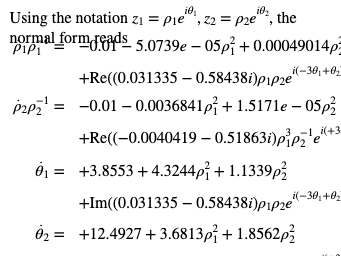

ROMOrder = 3;
freqNorm = [1 3];

RDInfo = IMDynamicsMech(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', 1,'N_PolyOrd', ROMOrder, 'style', 'normalform', ...
    'R_coeff',Ae,'rescale',1,'frequencies_norm',freqNorm,'MaxIter',5e3);


% We transform the truncated initial condition of our test trajectory according to 
% the obtained change of coordinates, and integrate our reduced order evolution rule 
% to predict the development of the trajectory. 
[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);

% Evaluation of reduced dynamics
% The error NMTE is computed as the average distance of the predicted trajectory 
% to the measured one in the full state space.
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
NMTE = mean(normedTrajDist(indTest))*100;
disp(['Normalized mean trajectory error = ' num2str(NMTE) '%'])

Normalized mean trajectory error = 9.7356%


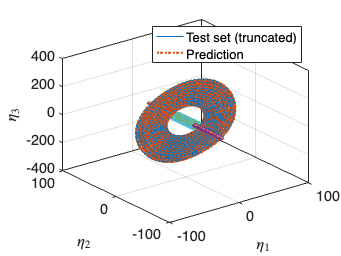


% We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 
plotReducedCoordinates(etaDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set (truncated)', 'Prediction'})
if size(Ae,1)==2
    % Plot SSM with trajectories in the normal form reduced coordinates
    plotSSMandTrajectories(IMInfo, outdof, yDataTrunc(indTest,:), ...
        zRec(indTest,:), 'NFT', RDInfo.transformation.map)
    view(-100,20); legend('off')
else
    view(3)
end

We also plot the measured and predicted tip displacement.

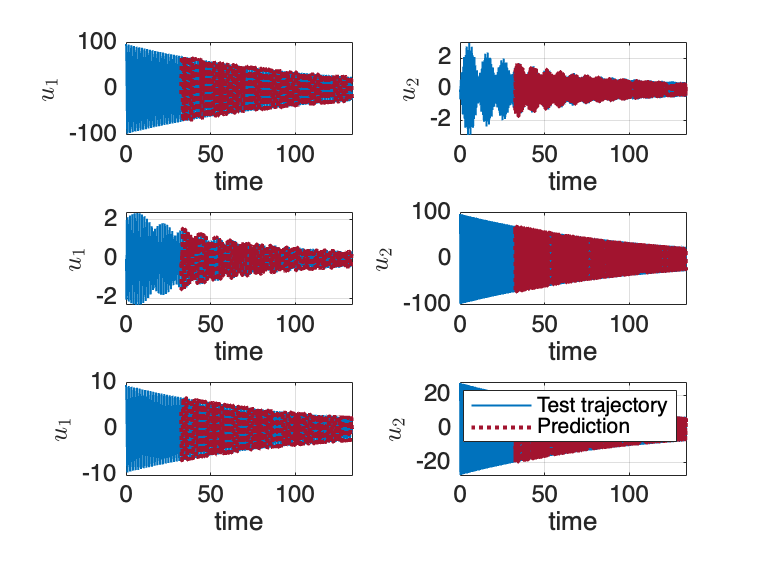

customFigure('subPlot',[3 2]); ipos = 0;
for iRow = 1:3
    for iCol = 1:2
        ipos = ipos+1;
        subplot(3,2,ipos)
        plot(yData{indTest(iRow),1},yData{indTest(iRow),2}(iCol,:),'k','Linewidth',1,'Color',colors(colFOM,:))
        plot(yRec{indTest(iRow),1},yRec{indTest(iRow),2}(iCol,:),':','Linewidth',2,'Color',colors(colSSML,:))
        xlabel('time')
        ylabel(['$u_' num2str(iCol) '$'],'interpreter','latex')
        xlim([yData{indTest(iRow),1}(1) yData{indTest(iRow),1}(end)])
    end
end
legend('Test trajectory','Prediction')

## Adding forcing to the ROM

% Outer directions: either consider all outer modes or a subset
numberOuterModes = (n-SSMDim)/2;
Vo = V(:,SSMDim+[1:2*numberOuterModes]); 
Wo = W(SSMDim+[1:2*numberOuterModes],:); Lo = full(Wo*A*Vo);
% Forcing vector
forcingVectors = [zeros(n,1); M\loadVector];
% Construct time periodic SSM model
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1,...
         'forcingVectors',forcingVectors,'We',We,'Lo',Lo,'Vo',Vo, 'Wo',Wo);

## Generate Frequency Responses via SSMLearn & SSMTool


 Run='SSMLearnFRC.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          9.26e-01  1.13e+01    0.0    0.0    0.0
   1   1  6.03e-02  8.07e+00  8.86e-01  1.14e+01    0.0    0.0    0.0
   2   2  3.82e-02  5.03e+00  6.54e-01  1.14e+01    0.0    0.0    0.0
   3   3  2.50e-01  1.94e-02  1.01e-01  1.14e+01    0.0    0.1    0.0
   4   1  1.00e+00  5.31e-02  3.53e-02  1.14e+01    0.0    0.1    0.0
   5   1  1.00e+00  8.53e-03  8.98e-04  1.14e+01    0.0    0.1    0.0
   6   1  1.00e+00  5.96e-05  8.00e-07  1.14e+01    0.0    0.1    0.0
   7   1  1.00e+00  9.30e-09  7.08e-13  1.14e+01    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   1.1385e+01      1  EP      3.8649e+00   5.3285e-02   8.6382e-05   2.6224e-01   7.0511e+00   4

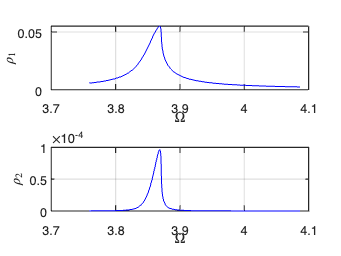

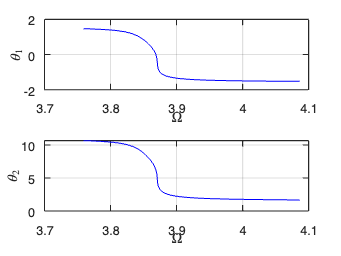


 Run='SSMLearnFRC.ep.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.96e-01  8.04e+00    0.0    0.0    0.0
   1   4  1.25e-01  2.62e-01  9.58e-01  8.03e+00    0.0    0.0    0.0
   2   1  4.71e-01  1.13e+00  8.72e-01  8.00e+00    0.0    0.0    0.0
   3   1  6.82e-02  6.20e+00  8.07e-01  7.99e+00    0.0    0.0    0.0
   4   3  3.96e-02  2.10e+00  7.13e-01  7.99e+00    0.0    0.0    0.0
   5   4  1.25e-01  1.05e-01  2.92e-01  7.99e+00    0.0    0.0    0.0
   6   2  5.00e-01  1.34e-01  6.93e-02  7.99e+00    0.0    0.0    0.0
   7   1  1.00e+00  9.32e-02  5.42e-03  7.99e+00    0.0    0.0    0.0
   8   1  1.00e+00  1.48e-02  4.13e-04  7.99e+00    0.0    0.0    0.0
   9   1  1.00e+00  2.32e-04  2.86e-07  7.99e+00    0.0    0.0    0.0
  10   1  1.00e+00  7.62e-08  5.59e-14  7.99e+00    0.0    0.0    0.0

 STEP      TIME    

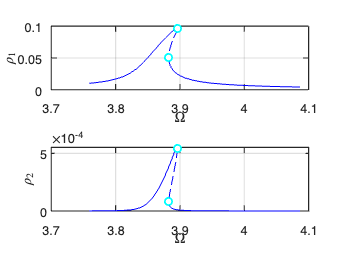

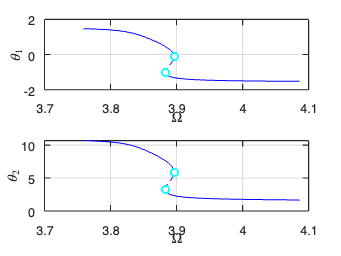

mFreqs = [1 3];
resonantModes = [1 2 3 4];
omegaSpan = [0.975 1.06]*imag(lambda(1));
epsilon = [.4 .7];
outdofs = [outdof1 outdof2];
[FRCSSMLearn] = continuationFRCep(IMInfoF, RDInfoF, epsilon, omegaSpan,@(x) x(outdofs,:), mFreqs,resonantModes, 'SSMLearnFRC');

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.593810e-03
modal damping ratio for 2 mode is 8.004681e-04
modal damping ratio for 3 mode is 3.837148e-04
modal damping ratio for 4 mode is 2.243713e-04
modal damping ratio for 5 mode is 1.470421e-04

 The first 10 nonzero eigenvalues are given as 
        -0.01 +     3.8553i
        -0.01 -     3.8553i
        -0.01 +     12.493i
        -0.01 -     12.493i
        -0.01 +     26.061i
        -0.01 -     26.061i
        -0.01 +     44.569i
        -0.01 -     44.569i
        -0.01 +     68.008i
        -0.01 -     68.008i

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:01
Estimated memory usage at order  2 = 6.78E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.01

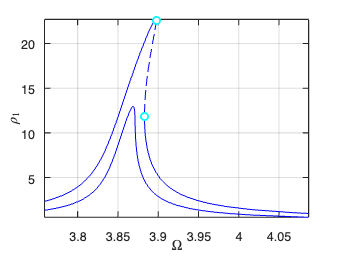

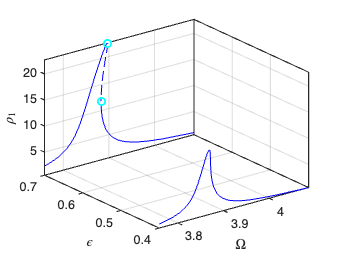

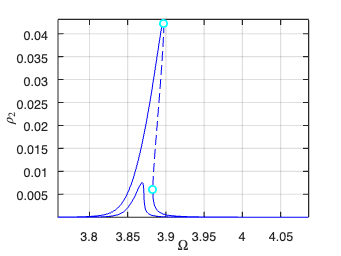

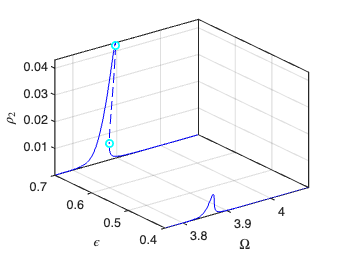

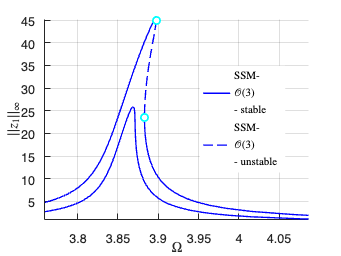

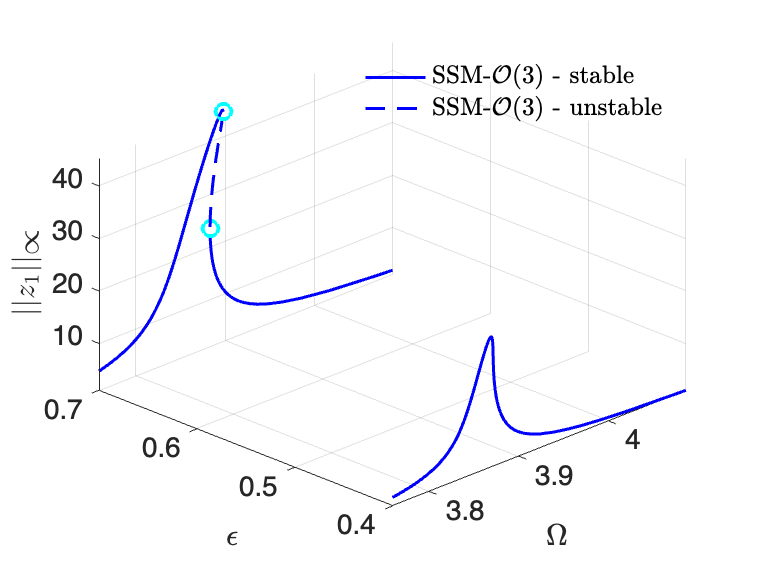

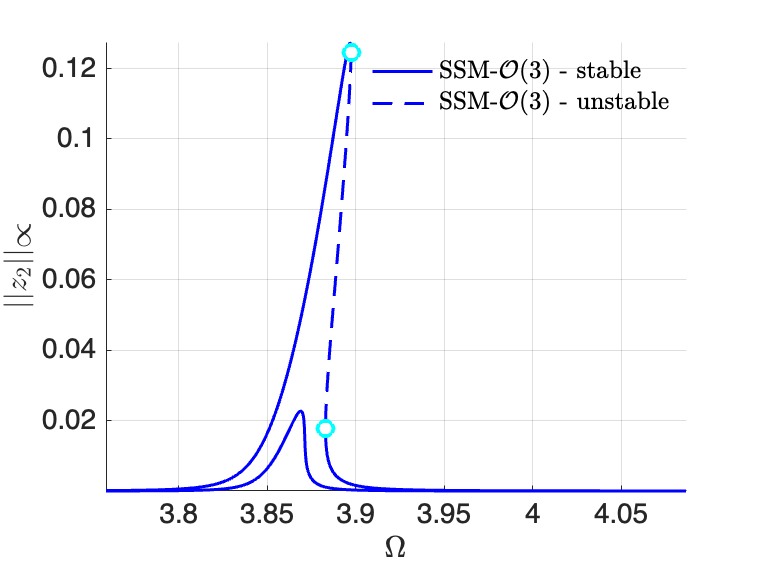

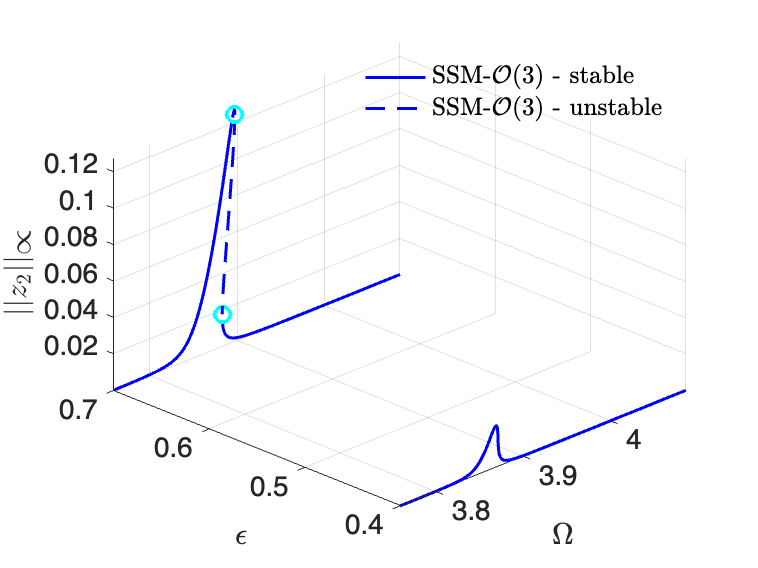

[FRCSSMTool] = SSMToolFRCFE(M,C,K,fnl,fext,outdofs,epsilon,resonantModes,3,omegaSpan,mFreqs, 'SSMToolFRC');

## **Plot results**

Phases.

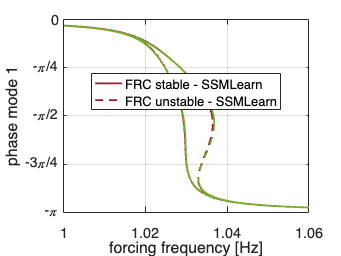

% Phase plot outdof 1
plotfreqscale = omegaSpan(1);
customFigure; 
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','y', 'Phase','freqscale',plotfreqscale)   
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','y', 'Phase','freqscale',plotfreqscale)
xlabel('forcing frequency [Hz]')
ylabel('phase mode 1')
xlim([1 1.06])
ylim([-pi 0 ])
set(gca,'YTick',[-pi -3/4*pi -pi/2 -pi/4 0])
set(gca,'YTickLabel',{'-\pi', '-3\pi/4', '-\pi/2', '-\pi/4', 0})

Amplitudes.

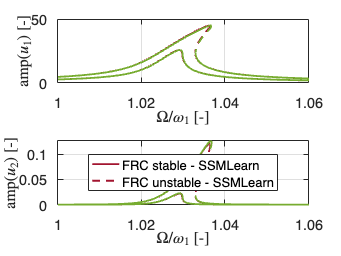

% Amplitude plot outdof 1 & 2
customFigure('subPlot',[ 2 1]); colors = colororder;
subplot(211)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',plotfreqscale)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','freqscale',plotfreqscale)
xlabel('$\Omega/\omega_{1}$ [-]','interpreter','latex')
ylabel('amp($u_{1}$) [-]','interpreter','latex')
legend('off')
xlim([1 1.06])
ylim([0 50])
subplot(212)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',plotfreqscale,'outamp',2)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','freqscale',plotfreqscale,'outamp',2)
xlabel('$\Omega/\omega_{1}$ [-]','interpreter','latex')
ylabel('amp($u_{2}$) [-]','interpreter','latex')
xlim([1 1.06])